clear;clc;
% Define the points and their associated areas
% For example, you can use the following data (z, y, area):
R=48;

points = [
    0 R  .5;
    -R*sind(45) R*sind(45) .5;
    -R 0 .5;
    -R*sind(45) -R*sind(45) .5;
    0 -R .5;
    R*sind(45) -R*sind(45) .5;
    R 0  .5;
    R*sind(45) R*sind(45) .5];


% Initialize variables to store the sum of weighted z and y coordinates
sum_weighted_z = 0;
sum_weighted_y = 0;
total_area = 0;

% Calculate the weighted sum of z and y coordinates
for i = 1:size(points, 1)
    z = points(i, 1); % Replace x with z
    y = points(i, 2);
    area = points(i, 3);
    
    sum_weighted_z = sum_weighted_z + (z * area);
    sum_weighted_y = sum_weighted_y + (y * area);
    
    total_area = total_area + area;
end

% Calculate the centroid
centroid_z = sum_weighted_z / total_area;
centroid_y = sum_weighted_y / total_area;

% Shift the points to the centroid's reference frame
points_shifted = points;
points_shifted(:, 1) = points_shifted(:, 1) - centroid_z; % Adjust the first column (formerly x) to z
points_shifted(:, 2) = points_shifted(:, 2) - centroid_y;

% Display the centroid coordinates
fprintf('Centroid Coordinates: (%.2f, %.2f)\n', centroid_z, centroid_y);

Centroid Coordinates: (0.00, 0.00)



% Display the shifted points in terms of the centroid's reference frame
fprintf('Shifted Points:\n');

Shifted Points:


disp(points_shifted);

         0   48.0000    0.5000
  -33.9411   33.9411    0.5000
  -48.0000         0    0.5000
  -33.9411  -33.9411    0.5000
         0  -48.0000    0.5000
   33.9411  -33.9411    0.5000
   48.0000         0    0.5000
   33.9411   33.9411    0.5000



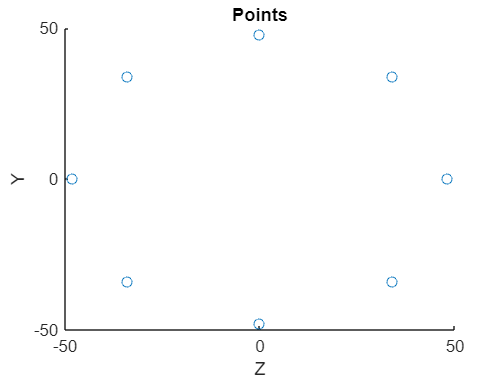


%plot points to validate
scatter(points_shifted(:,1), points_shifted(:,2));
xlabel('Z');
ylabel('Y');
title('Points');


%I am very dyslexic
shifted_points = points_shifted;
Iy = 0;
Iz = 0;
Iyz = 0;
for i = 1:size(shifted_points, 1)
    z = shifted_points(i, 1); % Replace x with z
    y = shifted_points(i, 2);
    area = shifted_points(i, 3);

    Iy = shifted_points(i, 3)*z^2 + Iy;
    Iz = shifted_points(i, 3)*y^2 + Iz;
    Iyz = shifted_points(i, 3)*z*y + Iyz;


end
fprintf('Iy = %.4f in^4\n', Iy);

Iy = 4608.0000 in^4


fprintf('Iz = %.4f in^4\n', Iz);

Iz = 4608.0000 in^4


fprintf('Iyz = %.4f in^4\n', Iyz);

Iyz = 0.0000 in^4





%show shear flow equation
vy = 800;
vz = 700;

syms y_bar z_bar A_bar q_in q_out Vy_bar Vz_bar

disp('shear stess with A v & y for find shear center:')

shear stess with A v & y for find shear center:


delta_q_withV = ((Iy*Vy_bar-Iyz*Vz_bar)*y_bar*A_bar + (-Iyz*Vy_bar + Iz*Vz_bar)*z_bar*A_bar)/(Iy*Iz-Iyz^2);
disp(vpa(delta_q_withV,4))

$$0.000217\,\bar{A}\,\bar{\mathrm{Vy}}\,\bar{y}+0.000217\,\bar{A}\,\bar{\mathrm{Vz}}\,\bar{z}$$


disp('Normal shear stress equation:')

Normal shear stress equation:


delta_q = ((Iy*vy-Iyz*vz)*y_bar*A_bar + (-Iyz*vy + Iz*vz)*z_bar*A_bar)/(Iy*Iz-Iyz^2);
disp(vpa(delta_q,4))

$$0.1736\,\bar{A}\,\bar{y}+0.1519\,\bar{A}\,\bar{z}$$


for points_stress_num = 1:length(shifted_points)


    delta_q_onlyV(points_stress_num) = ((Iy*Vy_bar-Iyz*Vz_bar)*shifted_points(points_stress_num,2)*shifted_points(points_stress_num,3) + (-Iyz*Vy_bar + Iz*Vz_bar)*shifted_points(points_stress_num,1)*shifted_points(points_stress_num,3))/(Iy*Iz-Iyz^2);

end

disp('POINTS shear stress equations in ONLY RIGHT SIDE, manually do deltaQ')

POINTS shear stress equations in ONLY RIGHT SIDE, manually do deltaQ


disp(vpa(delta_q_onlyV',4))

$$\left(\begin{array}{c} 0.005208\,\bar{\bar{\mathrm{Vy}}}\\ 0.003683\,\bar{\bar{\mathrm{Vy}}}-0.003683\,\bar{\bar{\mathrm{Vz}}}\\ -0.005208\,\bar{\bar{\mathrm{Vz}}}\\ -0.003683\,\bar{\bar{\mathrm{Vy}}}-0.003683\,\bar{\bar{\mathrm{Vz}}}\\ -0.005208\,\bar{\bar{\mathrm{Vy}}}\\ 0.003683\,\bar{\bar{\mathrm{Vz}}}-0.003683\,\bar{\bar{\mathrm{Vy}}}\\ 0.005208\,\bar{\bar{\mathrm{Vz}}}\\ 0.003683\,\bar{\bar{\mathrm{Vy}}}+0.003683\,\bar{\bar{\mathrm{Vz}}} \end{array}\right)$$

deltaqtmp = subs(delta_q_onlyV, [Vy_bar,Vz_bar],[vy,vz])'

$$deltaqtmp = \left(\begin{array}{c} \frac{25}{6}\\ \frac{25\,\sqrt{2}}{96}\\ -\frac{175}{48}\\ -\frac{125\,\sqrt{2}}{32}\\ -\frac{25}{6}\\ -\frac{25\,\sqrt{2}}{96}\\ \frac{175}{48}\\ \frac{125\,\sqrt{2}}{32} \end{array}\right)$$

disp(vpa(deltaqtmp ,4))

$$\left(\begin{array}{c} 4.167\\ 0.3683\\ -3.646\\ -5.524\\ -4.167\\ -0.3683\\ 3.646\\ 5.524 \end{array}\right)$$



syms q12 q18 q23 q34 q45 q56 q67 q78 q24 q46

eqn1 = q12-q18 == deltaqtmp(1)

$$eqn1 = q_{12}-q_{18}=\frac{25}{6}$$

eqn2 = q23-q12-q24 == deltaqtmp(2)

$$eqn2 = q_{23}-q_{12}-q_{24}=\frac{25\,\sqrt{2}}{96}$$

eqn3 = q34-q23 == deltaqtmp(3)

$$eqn3 = q_{34}-q_{23}=-\frac{175}{48}$$

eqn4 = q24+q46+q45-q34 == deltaqtmp(4)

$$eqn4 = q_{24}-q_{34}+q_{45}+q_{46}=-\frac{125\,\sqrt{2}}{32}$$

eqn5 = q56-q45 == deltaqtmp(5)

$$eqn5 = q_{56}-q_{45}=-\frac{25}{6}$$

eqn6 = q67-q46-q56 == deltaqtmp(6)

$$eqn6 = q_{67}-q_{56}-q_{46}=-\frac{25\,\sqrt{2}}{96}$$

eqn7 = q78-q67 == deltaqtmp(7)  

$$eqn7 = q_{78}-q_{67}=\frac{175}{48}$$

eqn8 = q18-q78 == deltaqtmp(8)

$$eqn8 = q_{18}-q_{78}=\frac{125\,\sqrt{2}}{32}$$

 %redundants are q23 q34 q45 q56, 24 45
 %Variables = [q12 q18 q23 q34 q45 q56 q67 q78 q24 q46]
 Variables = [q12 q18 q23 q34 q45 q56 q67 q78];
[q12, q18, q23, q34, q45, q56, q67, q78] = solve([eqn1,eqn2,eqn3,eqn4,eqn5,eqn6,eqn7,eqn8],Variables)

$$q12 = \frac{125\,\sqrt{2}}{32}+\frac{25}{6}$$

$$q18 = \frac{125\,\sqrt{2}}{32}$$

$$q23 = q_{24}+\frac{25\,\sqrt{2}}{6}+\frac{25}{6}$$

$$q34 = q_{24}+\frac{25\,\sqrt{2}}{6}+\frac{25}{48}$$

$$q45 = \frac{25\,\sqrt{2}}{96}-q_{46}+\frac{25}{48}$$

$$q56 = \frac{25\,\sqrt{2}}{96}-q_{46}-\frac{175}{48}$$

$$q67 = -\frac{175}{48}$$

$$q78 = 0$$

fprintf("q12= %.4f",q12)

q12= 9.6909


T = 700*R*sind(45)-800*R*sind(45);
fprintf("T= %.4f",T)

T= -3394.1125

A1 = pi*R^2/8; fprintf("A1 is: %.4f",A1);

A1 is: 904.7787

A2 = .5*R^2*(pi/2-sind(90));fprintf("A2 is: %.4f",A2);

A2 is: 657.5574


momenteqn = T ==2*A1*(q12+q23+q34+q45+q56+q67+q78+q18)+2*A2*(q46-q24);
fprintf("moment equation is:")

moment equation is:

disp(vpa(momenteqn,3))

$$-3390.0=2300.0\,q_{24}-2300.0\,q_{46}+4.64e+4$$


q24 = solve(momenteqn, q24);
disp("q24 = ");disp(vpa(q24,4));

q24 = 


$$1.0\,q_{46}-21.62$$


 
% Create a cell array of symbolic variables
tmpmatrix = {q12, q18, q23, q34, q45, q56, q67, q78};

% Substitute each variable with q24
for i = 1:numel(tmpmatrix)
    tmpmatrix{i} = subs(tmpmatrix{i}, q24);
    disp(vpa(tmpmatrix{i}, 4));
end

$$9.691$$

$$5.524$$

$$1.0\,q_{46}-11.56$$

$$1.0\,q_{46}-15.21$$

$$22.51-1.0\,q_{46}$$

$$18.34-1.0\,q_{46}$$

$$-3.646$$

$$0.0$$


% Convert cell array back to a symbolic array
[tmpmatrix{:}] = deal(tmpmatrix{:});

% Display the updated tmpmatrix
disp(vpa(tmpmatrix, 4));

$$\left(\begin{array}{cccccccc} 9.691 & 5.524 & 1.0\,q_{46}-11.56 & 1.0\,q_{46}-15.21 & 22.51-1.0\,q_{46} & 18.34-1.0\,q_{46} & -3.646 & 0 \end{array}\right)$$


% Reassign the values to the symbolic variables
[q12, q18, q23, q34, q45, q56, q67, q78] = tmpmatrix{:};


syms dq12 dq18 dq23 dq34 dq45 dq56 dq67 dq78 dq24 dq46
dq12=0

dq12 = 0

dq18 = 0

dq18 = 0

dq23 = dq46

$$dq23 = {\mathrm{dq}}_{46}$$

dq34 =dq46

$$dq34 = {\mathrm{dq}}_{46}$$

dq45 = -dq46

$$dq45 = -{\mathrm{dq}}_{46}$$

dq56 = -dq46

$$dq56 = -{\mathrm{dq}}_{46}$$

dq67 = 0

dq67 = 0

dq78 = 0

dq78 = 0

dq24=dq46

$$dq24 = {\mathrm{dq}}_{46}$$


A3 =2*pi*R*240/8

A3 = 9.0478e+03

A4 = R*sin(pi/4)*240

A4 = 8.1459e+03


virteqn = 0 ==(A3*(q34*dq34+q23*dq23+q45*dq45+q56*dq56)+A4*(q24*dq24+q46*dq46))/(3.9*10^6*.045);
disp(vpa(virteqn,3))

$$0.0=0.0464\,{\mathrm{dq}}_{46}\,q_{46}+0.0516\,{\mathrm{dq}}_{46}\,\left(1.0\,q_{46}-18.3\right)+0.0516\,{\mathrm{dq}}_{46}\,\left(1.0\,q_{46}-22.5\right)+0.0516\,{\mathrm{dq}}_{46}\,\left(1.0\,q_{46}-11.6\right)+2.01e-5\,{\mathrm{dq}}_{46}\,\left(2300.0\,q_{46}-4.98e+4\right)+0.0516\,{\mathrm{dq}}_{46}\,\left(1.0\,q_{46}-15.2\right)$$


collected_terms = vpa(collect(virteqn,[dq46,dq24]),4)

$$collected\_terms = 0.0={\mathrm{dq}}_{46}\,\left(0.299\,q_{46}-4.49\right)$$


tmpeqn = 0 == .299*q46-4.49;
q46 = solve(tmpeqn)

$$q46 = \frac{4490}{299}$$

disp(double(q46))

   15.0167








% Create a cell array of symbolic variables
tmpmatrix = {q12, q18, q23, q34, q45, q56, q67, q78};

% Substitute each variable with q24
for i = 1:numel(tmpmatrix)
    tmpmatrix{i} = subs(tmpmatrix{i}, q46);
    disp(vpa(tmpmatrix{i}, 4));
end

$$9.691$$

$$5.524$$

$$3.455$$

$$-0.1913$$

$$7.494$$

$$3.327$$

$$-3.646$$

$$0.0$$


% Convert cell array back to a symbolic array
[tmpmatrix{:}] = deal(tmpmatrix{:});

% Display the updated tmpmatrix
disp(vpa(tmpmatrix, 4));

$$\left(\begin{array}{cccccccc} 9.691 & 5.524 & 3.455 & -0.1913 & 7.494 & 3.327 & -3.646 & 0 \end{array}\right)$$


% Reassign the values to the symbolic variables
[q12, q18, q23, q34, q45, q56, q67, q78] = tmpmatrix{:};

A5 = R^2*(90*pi/360-sind(90)/2)

A5 = 657.5574

dtheta = (-q46*2*R*sind(45)+2*pi*R/8*(q56+q45))/(2*A5*3.9*10^6*0.045);
disp(vpa(dtheta,4))

$$-2.649e-6$$

theta = dtheta/-180;
disp(vpa(theta,4))

$$1.472e-8$$